# Visualize Electro-Magnetic Spherical Waves

This script is a simple visualization of a spherical wave. Through a series of snapshots, the script creates a movie (F) that model the behaivor of the wave with certain parameters. 

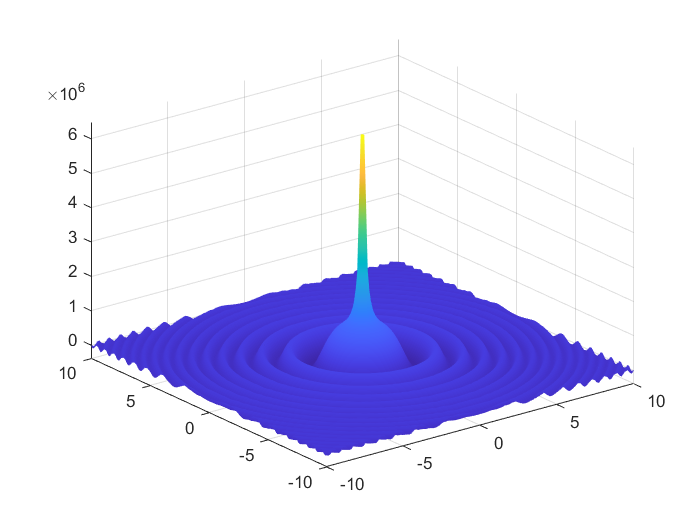

% Clear variables, command window and figures
clear;clc;clf;

% Define general parameters
lamda=3*10^(-7);        %wavelength[m]
A = 800000;             %[Amplitude]
c = 3*10^5;             %[m/s]
N= 150;     %Definition of the problem

% Define space
% x = linspace(0.5,100,N);
x = linspace(-10,10,N);
y = linspace(-10,10,N);
[X,Y]=meshgrid(x,y);
R=(X.^2+Y.^2)^1/2;  %Radial 

% Define time
t=linspace(1,N,N);

% Calculate wave parameters
k=2*pi/lamda;   %Wavenumber [1/m]
w=c*k;          %Angular frequency [1/s]

% Initialize wave
u = zeros(N,N,N);   %Preallocate (space, space, time)
u(:,:,1)= (1./sqrt(R)).*A.*cos(R-t(1));
% Visualize first frame
fig = figure;
surf(X,Y,u(:,:,1));
shading interp
axis tight manual

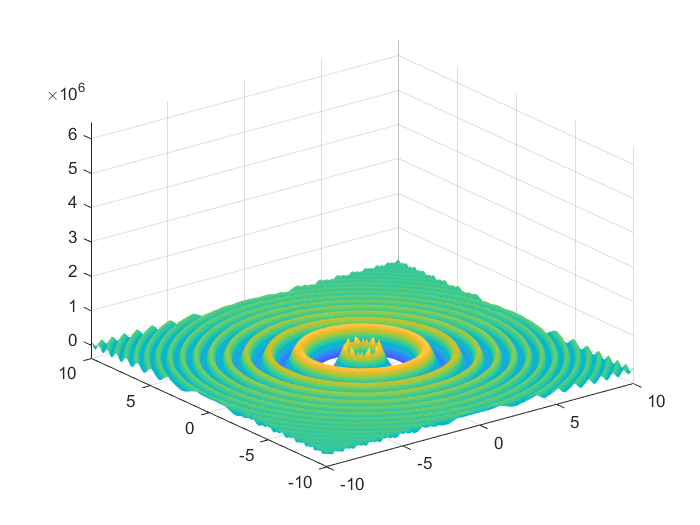

% Capture the frames
ax = gca;   %Get axes
ax.NextPlot = 'replaceChildren'; %Removes all axes objects. Does not reset figure properties
F(t(end)) = struct('cdata',[],'colormap',[]);

% Propagate
for ii = 1:t(end)
    u(:,:,ii)= (1./sqrt(R)).*A.*cos(R-t(ii)) .*(R>0.4);
    surf(X,Y,u(:,:,ii));
    shading interp
    F(ii) = getframe;
end

movie(F) %Run this line on comand window